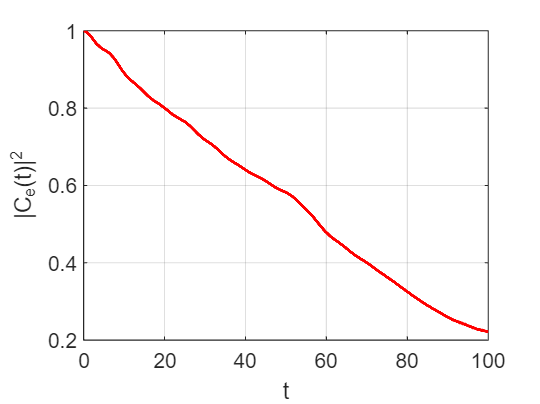

% Clear workspace, command window, and close all figures
clear;
clc;
close all;


% Parameters
N = 51; % Example value, you can change it
g = 0.1;   % Coupling strength g
J = 2;   % Coupling constant J
J_prime = 1; % Coupling constant J'
omega = 5; % Modulation frequency omega
Delta = - omega * 0.4;  % Detuning parameter Delta
V = 0.2;   % Modulation amplitude V
j_0 = (N-1)/2;

dt = 0.01;  % Time step for numerical integration
T = 100;   % Total simulation time
% Time vector
time = 0:dt:T;
num_steps = length(time);


% Define the Hamiltonian function
Ht = @(t) Hamilontian(t, N, J, J_prime, V, omega, g, Delta);

% Initialize the qubit in the excited state
psi_0 = zeros(2*N+1, 1);
psi_0(end) = 1;


% 调用runge_kutta_solver函数
psi_t = runge_kutta_timedependent(Ht, psi_0, time);



% Plot |C_e(t)|^2 vs time
figure;
plot(time, abs(psi_t(end, :)).^2, 'r', 'LineWidth', 1.5);
xlabel('t');
ylabel('|C_{e}(t)|^2');
grid on;

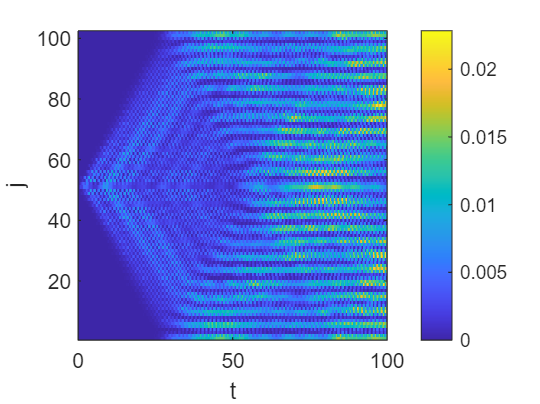



psi_ab = psi_t;
% Fourier transform a_k ---> a_j
psi_ab_x = zeros(2*N);
k = linspace(-pi, pi, N);
x = (-(N-1)/2:(N-1)/2)';
fft = exp(1i .* kron(x, k)) / sqrt(N);
for i = 1:num_steps
    psi_ab_x(1:2:2*N-1, i) = fft * psi_ab(1:2:2*N-1,i); % a_k ---> a_x
    psi_ab_x(2:2:2*N, i) = fft * psi_ab(2:2:2*N,i); % b_k ---> b_x
end

% Plot |B_j(t)|^2 as a heatmap
figure;
imagesc(time, 1:2*N, abs(psi_ab_x).^2);
colorbar;
xlabel('t');
ylabel('j');
set(gca, 'YDir', 'normal'); % Ensure y-axis is correctly oriented


% Define function for the derivative


function H = Hamilontian(t, N, J, J_prime, V, omega, g, Delta)
    vt = 2 * V * cos(omega * t);
    kk = linspace(-pi, pi, N);
    J1 = J + vt;
    J2 = J_prime - vt;

    % Create the Hamiltonian matrix
    H = zeros(2*N + 1); % Include additional state for the qubit
    H(end, end) = Delta;
    for i = 1:1:N
        k = kk(i);
        H(2*i-1,2*i) = J1 + J2 * exp(1i * k); % a_k^+ b_k
        H(2*i,2*i-1) = J1 + J2 * exp(-1i * k); % a_k^+ b_k

        H(end, 2*i-1) = g / sqrt(N);
        H(2*i-1, end) = g / sqrt(N);

    end

end


